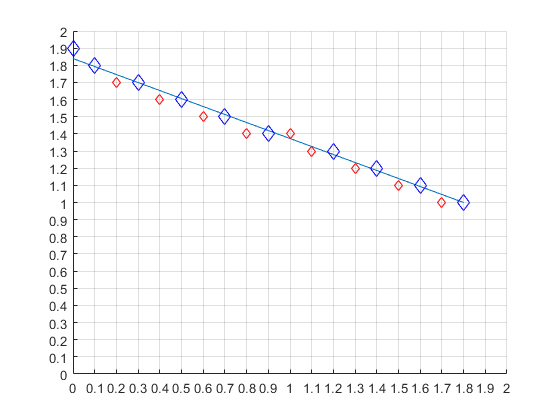

clear
clc
N = 20;
grid_max = 2;
x_grid = 0:grid_max/N:grid_max;
y_grid = 0:grid_max/N:grid_max;
figure();
grid on
xticks(x_grid)
yticks(y_grid)
xlim([x_grid(1),grid_max])
ylim([y_grid(1),grid_max])

x0 = 1.8;
y0 = 1;
a = tand(65+90);

syms x_sym
hold on
fplot(func(x_sym, x0, y0, a),[0 x0])
clear x_sym

% j = ceil(y0 / grid_max * N);
% for i = 1 + ceil(x0 / grid_max * N):length(x_grid) - 1
%     counter = 0;
%     y = func(x_grid(i), x0, y0);
%     if (y > grid_max)
%         break;
%     end
%     if func(x_grid(i + 1), x0, y0) > y
%         while abs(y_grid(j+1) - y) < abs(y - y_grid(j))
%             j = j + 1;
%             counter = counter + 1;
%             if (j + 1 > length(y_grid))
%                 break;
%             end
%         end
%     else
%         while abs(y_grid(j-1) - y) < abs(y - y_grid(j))
%             j = j - 1;
%             counter = counter + 1;
%             if (j + 1 > length(y_grid))
%                 break;
%             end
%         end
%         
%     end
%     if (counter > 1) && (i > 1)
%         for k = 1:floor(counter/2)
%             scatter(x_grid(i-1),y_grid(j - counter + k),'rd')
%         end
%         for k = floor(counter/2) + 1:counter - 1
%             scatter(x_grid(i),y_grid(j - counter + k),'rd')
%         end
%     end
%     scatter(x_grid(i),y_grid(j),'bd',"SizeData",80);
% end
% hold off

% i = ceil(x0 / grid_max * N) + 1;
% for j = 1 + ceil(y0 / grid_max * N):length(y_grid) - 1
%     counter = 0;
%     x = func_inv(y_grid(j), x0, y0, grid_max, func(grid_max,x0,y0,a));
%     if (x > grid_max)
%         break;
%     end
%     if func_inv(y_grid(j + 1), x0, y0, grid_max, func(grid_max,x0,y0,a)) > x
%         while abs(x_grid(i+1) - x) < abs(x - x_grid(i))
%             i = i + 1;
%             counter = counter + 1;
%             if (i + 1 > length(x_grid))
%                 break;
%             end
%         end
%     else
%         while abs(x_grid(i-1) - x) < abs(x - x_grid(i))
%             i = i - 1;
%             counter = counter + 1;
%             if (i + 1 > length(x_grid))
%                 break;
%             end
%         end
%         
%     end
%     if (counter > 1) && (j > 1)
%         for k = 1:floor(counter/2)
%             scatter(x_grid(i - counter + k),y_grid(j-1),'rd')
%         end
%         for k = floor(counter/2) + 1:counter - 1
%             scatter(x_grid(i - counter + k),y_grid(j),'rd')
%         end
%     end
%     scatter(x_grid(i),y_grid(j),'bd',"SizeData",80);
% end
% hold off

i = ceil(x0 / grid_max * N) + 1;
for j = 1 + ceil(y0 / grid_max * N):length(y_grid) - 1
    if i - 1 <= 0
        break;
    end
    counter = 0;
    x = func_inv(y_grid(j), x0, y0, grid_max, func(grid_max,x0,y0,a));
    if (x > grid_max)
        break;
    end
    if func_inv(y_grid(j + 1), x0, y0, grid_max, func(grid_max,x0,y0,a)) > x
        while abs(x_grid(i+1) - x) < abs(x - x_grid(i))
            i = i + 1;
            counter = counter + 1;
        end
    else
        while abs(x_grid(i-1) - x) < abs(x - x_grid(i))
            i = i - 1;
            counter = counter + 1;
            if (i - 1 <= 0)
                break;
            end
        end
        
    end
    if (counter > 1) && (j > 1)
        for k = 1:floor(counter/2)
            scatter(x_grid(i + counter - k),y_grid(j-1),'rd')
        end
        for k = floor(counter/2) + 1:counter - 1
            scatter(x_grid(i + counter - k),y_grid(j),'rd')
        end
    end
    scatter(x_grid(i),y_grid(j),'bd',"SizeData",80);
end
hold off

function [y] = func(x, x0, y0, a)
% y = 0.3 + 1.55 * (x+0.4)^3 - 4.2*x^2;
y = a*(x-x0) + y0;
end

function [x] = func_inv(y, x0, y0, x_end, y_end)
x = x0 + (y - y0) * (x_end - x0) / (y_end - y0);
end